Playing head_f.wav at 24000 Hz with duration 0.24 seconds and 5648 samples


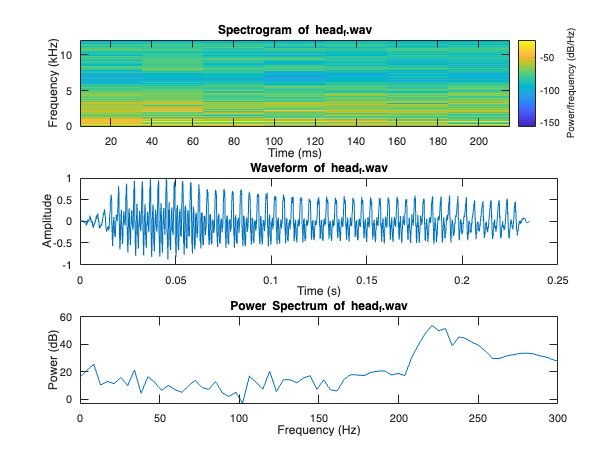

file_1 = 'head_f.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

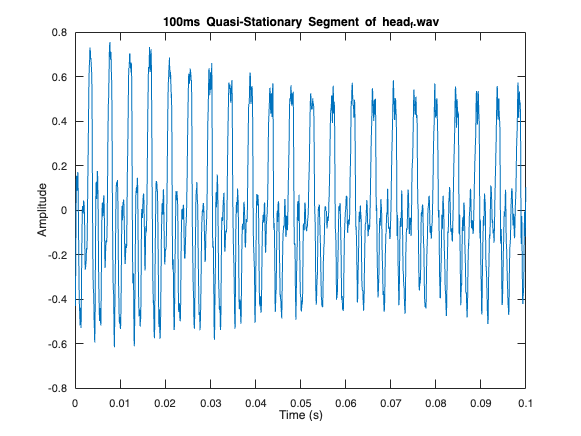

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);

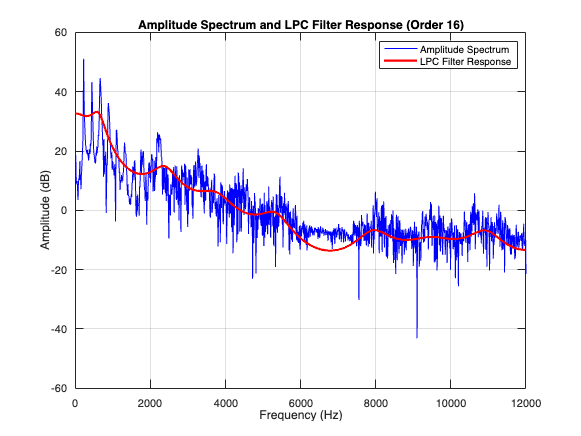

lpcOrder = 16;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 621.11 Hz
F2: 2382.03 Hz
F3: 3761.35 Hz


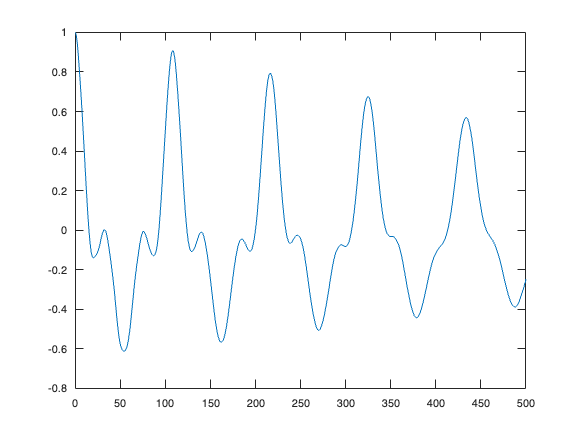

Estimated F0 using autocorrelation: 222.22 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 220.00 Hz


f0 = mean(pitch(segment, fs));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 221.01 Hz


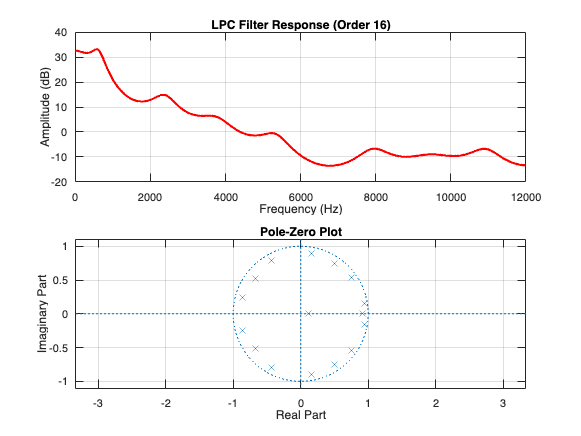

plotLPCPoleZero(segment, fs, lpcOrder);

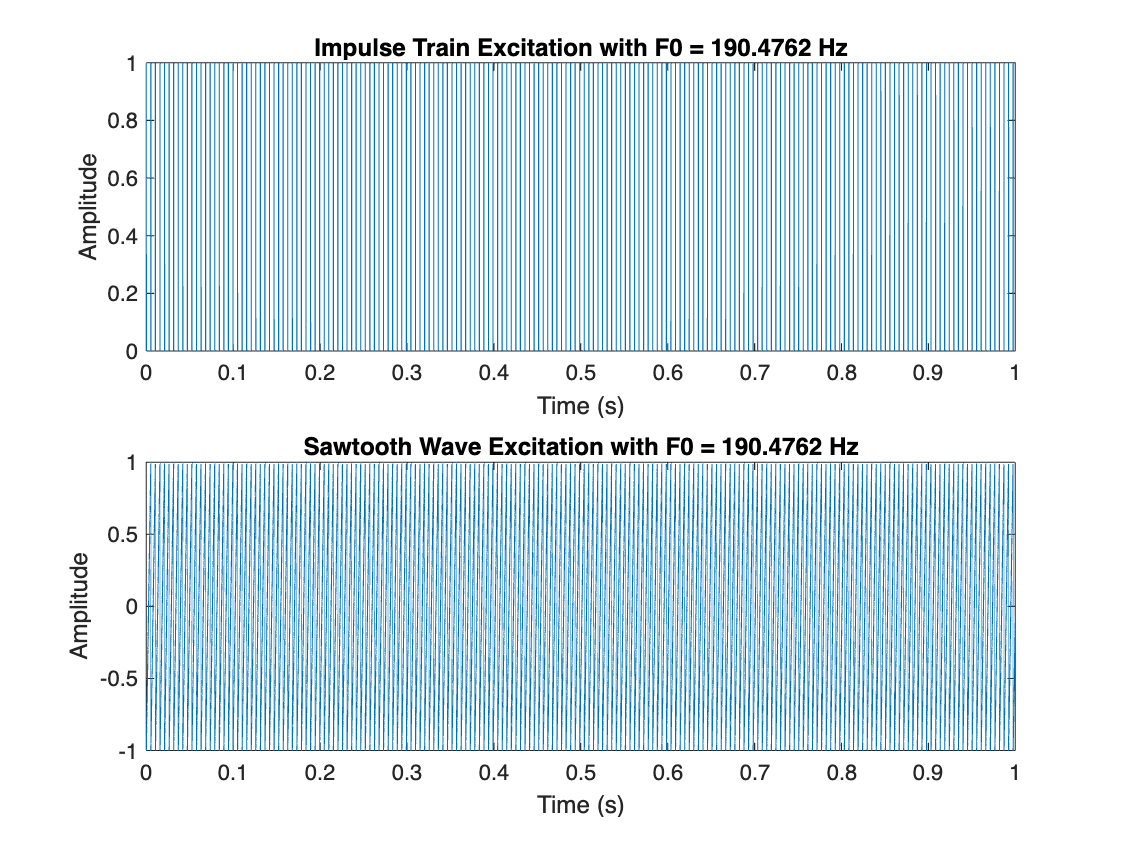

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1);

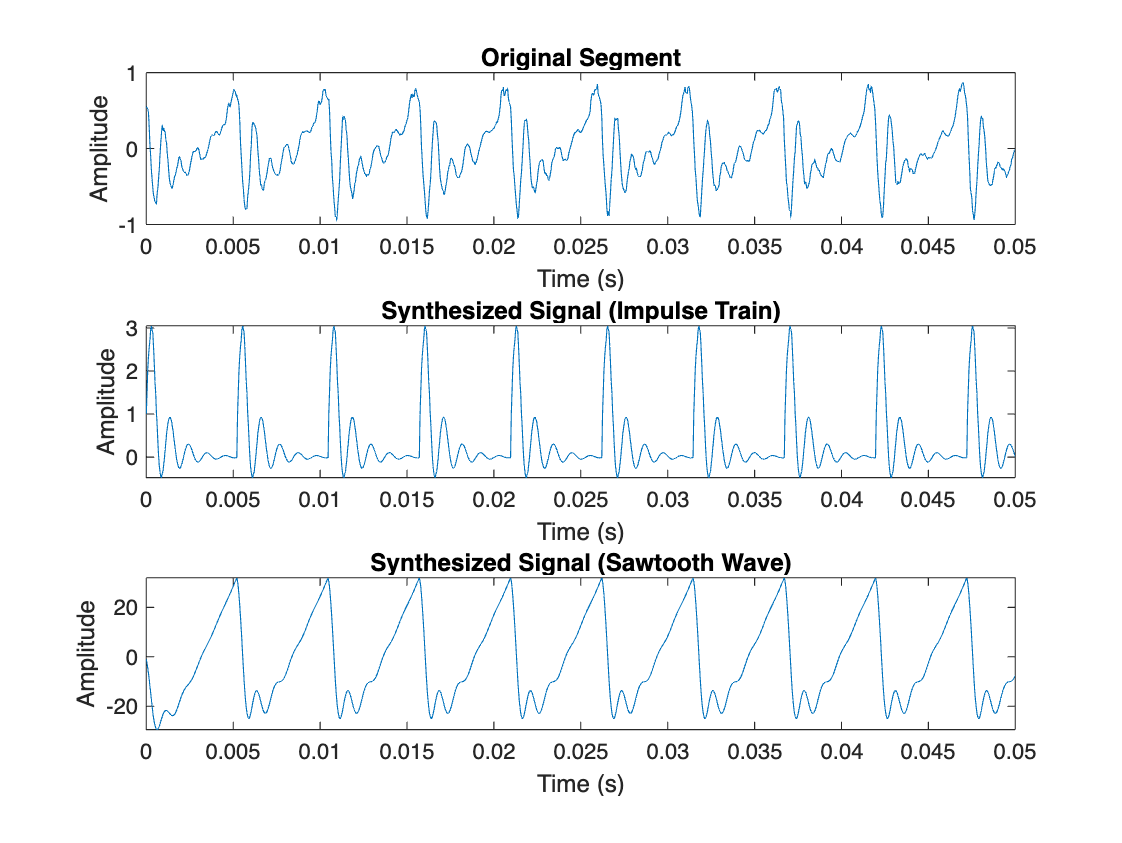

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);